% Experiment-4: Bounding Box Image Area as Input: Simple CNN : CUB_200_2011 Dataset 
% Author: Sujan Khanal
% ID: u3258630

close all;
clear variables;
clc;

rng(42, 'twister'); %% For reproducibility

%% STEP 1: Check and Reset GPU
if (gpuDeviceCount() > 0)
    disp('Found GPU:');
    disp(gpuDeviceTable);
    device = gpuDevice(1);
    reset(device); % Reset any old data
else
    error('No GPU device found. Please ensure GPU is available.');
end

Found GPU:


    Index              Name               ComputeCapability    DeviceAvailable    DeviceSelected
    _____    _________________________    _________________    _______________    ______________

      1      "NVIDIA GeForce RTX 3070"          "8.6"               true              true      



## Read the training, validation and test partitions from the relevant


folder = "C:\Users\u3258630\Desktop\CVIA\u3258630_CVIA_Asgn1_Final\CUB_200_2011\";
trainingImageNames = readtable(fullfile(folder, "train200.txt"), ...
    'ReadVariableNames', false);
trainingImageNames.Properties.VariableNames = {'index', 'imageName'};

validationImageNames = readtable(folder + "validate200.txt", ...
    'ReadVariableNames', false);
validationImageNames.Properties.VariableNames = {'index', 'imageName'};

testImageNames = readtable(folder + "test200.txt", ...
    'ReadVariableNames', false);
testImageNames.Properties.VariableNames = {'index', 'imageName'};

## Read class info from the relevant text files

classNames = readtable(folder + "classes.txt", ...
    'ReadVariableNames', false);
classNames.Properties.VariableNames = {'index', 'className'};

imageClassLabels = readtable(folder + "image_class_labels.txt", ...
    'ReadVariableNames', false);
imageClassLabels.Properties.VariableNames = {'index', 'classLabel'};

## Read bounding box information from bounding_boxes.txt. The format is

boundingBoxes = readtable(folder + "bounding_boxes.txt", ...
    'ReadVariableNames', false);
boundingBoxes.Properties.VariableNames = {'index', 'x', 'y', 'w', 'h'};

% Map bounding box information to the respective image file name
train_image_box_map = returnMapping(trainingImageNames, boundingBoxes);
val_image_box_map = returnMapping(validationImageNames, boundingBoxes);
test_image_box_map = returnMapping(testImageNames, boundingBoxes);

## Create lists of image names for training, validation and test subsets.

trainingImageList = strings(height(trainingImageNames), 1);
for iI = 1:height(trainingImageNames)
    trainingImageList(iI) = string(fullfile(folder, "images/", ...
        string(cell2mat(trainingImageNames.imageName(iI)))));
end

validationImageList = strings(height(validationImageNames), 1);
for iI = 1:height(validationImageNames)
    validationImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(validationImageNames.imageName(iI))));
end

testImageList = strings(height(testImageNames), 1);
for iI = 1:height(testImageNames)
    testImageList(iI) = string(folder + "images/" + ...
        string(cell2mat(testImageNames.imageName(iI))));
end

## Create image datastores for training, validation and test subsets

trainingImageDS = imageDatastore(trainingImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
trainingImageDS.ReadFcn = @(filename) readImagesIntoDatastoreBB_Fast(filename, train_image_box_map);
disp('Training set class samples:');

Training set class samples:


countEachLabel(trainingImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  



validationImageDS = imageDatastore(validationImageList, 'labelSource', 'foldernames', ...
    'FileExtensions', {'.jpg'});
validationImageDS.ReadFcn = @(filename) readImagesIntoDatastoreBB_Fast(filename, val_image_box_map);
disp('Validation set class samples:');

Validation set class samples:


countEachLabel(validationImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      12  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  



testImageDS = imageDatastore(testImageList, 'labelSource', 'foldernames',   'FileExtensions', {'.jpg'});
testImageDS.ReadFcn = @(filename) readImagesIntoDatastoreBB_Fast(filename, test_image_box_map);
disp('Test set class samples:');

Test set class samples:


countEachLabel(testImageDS)

ans = 200×2 table
    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  


## The images all have different spatial resolutions (width x height), so

% Combine transformed datastores and labels
labelsTraining = arrayDatastore(trainingImageDS.Labels);
labelsValidation = arrayDatastore(validationImageDS.Labels);
labelsTest = arrayDatastore(testImageDS.Labels);

cdsTraining = combine(trainingImageDS, labelsTraining);
cdsValidation = combine(validationImageDS, labelsValidation);
cdsTest = combine(testImageDS, labelsTest);

% Resize all images to a common width and height
targetSize = [128, 128];
cdsTraining = transform(cdsTraining, @(x) preprocessData(x,targetSize));
cdsValidation = transform(cdsValidation, @(x) preprocessData(x,targetSize));
cdsTest = transform(cdsTest, @(x) preprocessData(x,targetSize));

## Display a sample image from the datastore

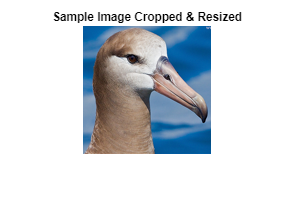

figure(1);
imshow(cdsTraining.read{1});
title('Sample Image Cropped & Resized');

## Create a simple CNN

%% Create CNN Layers
layers = [
    imageInputLayer([128 128 3], 'Normalization', 'zerocenter')

    convolution2dLayer(3, 16, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 32, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 64, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 128, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 256, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    convolution2dLayer(3, 512, 'Padding', 'same')
    batchNormalizationLayer
    reluLayer

    maxPooling2dLayer(2, 'Stride', 2)

    fullyConnectedLayer(200, 'WeightLearnRateFactor', 10, 'BiasLearnRateFactor', 10)
    softmaxLayer
    classificationLayer
];


## Set the training options

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.001, ...  % Lower learning rate to prevent large updates
    'MiniBatchSize', 64, ...
    'MaxEpochs', 30, ...  % Increased epochs
    'Shuffle', 'every-epoch', ...  
    'ValidationData', cdsValidation, ...
    'ValidationFrequency',50, ...
    'ExecutionEnvironment', 'gpu', ...
    'Verbose', true, ...
    'VerboseFrequency', 50, ...
    'Plots', 'training-progress', ...
    'ValidationPatience', 7); 


## Train the simple CNN model

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:33 |        0.00% |        1.01% |       6.5689 |      31.9173 |          0.0010 |
|       1 |          50 |       00:01:14 |        0.00% |        1.43% |       9.4016 |       7.8711 |          0.0010 |
|       1 |         100 |       00:01:56 |        1.56% |        1.22% |       7.8415 |       6.4467 |          0.0010 |
|       2 |         150 |       00:02:41 |        3.12% |        2.70% |       5.0559 |       5.7260 |          0.

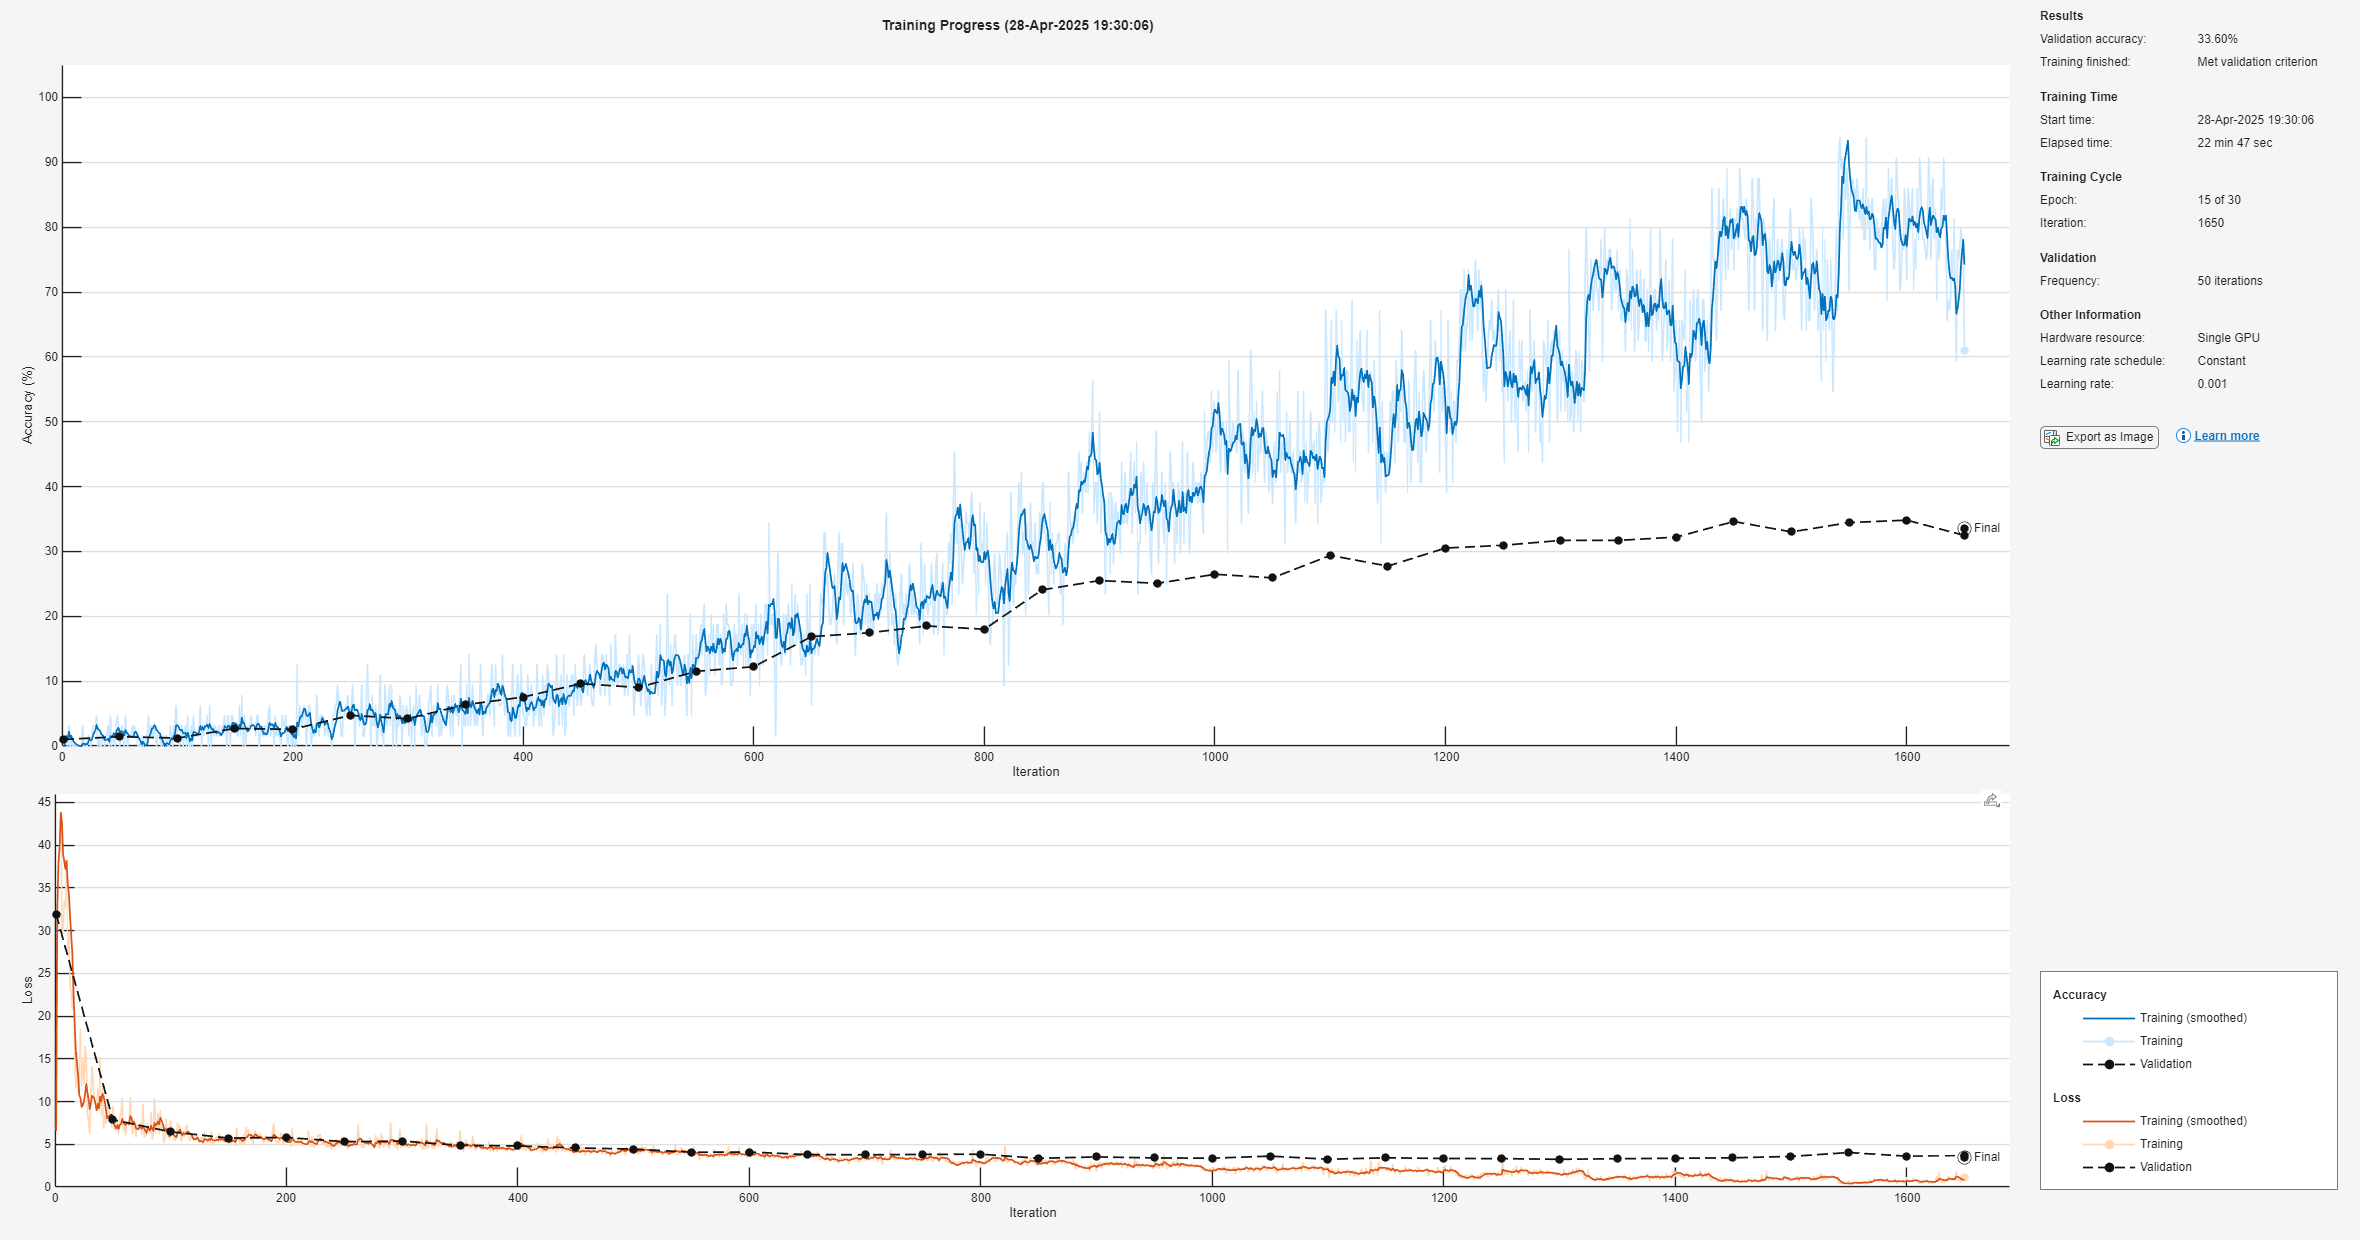

simpleCNN = trainNetwork(cdsTraining, layers, options);

## Test the accuracy on the test partition

YPred = classify(simpleCNN, cdsTest, 'ExecutionEnvironment', 'gpu');
YTest = testImageDS.Labels;

YPredTrain = classify(simpleCNN, cdsTraining, 'ExecutionEnvironment', 'gpu');
YTrain = trainingImageDS.Labels;

YPredValidation = classify(simpleCNN, cdsValidation, 'ExecutionEnvironment', 'gpu');
YValidation = validationImageDS.Labels;

trainAccuracy = sum(YPredTrain == YTrain) / numel(YTrain);
validationAccuracy = sum(YPredValidation == YValidation) / numel(YValidation);
testAccuracy = sum(YPred == YTest) / numel(YTest);

disp(['Training Accuracy: ', num2str(trainAccuracy * 100, '%.2f'), '%']);

Training Accuracy: 85.46%


disp(['Validation Accuracy: ', num2str(validationAccuracy * 100, '%.2f'), '%']);

Validation Accuracy: 33.60%


disp(['Test Accuracy: ', num2str(testAccuracy * 100, '%.2f'), '%']);

Test Accuracy: 33.43%



% Calculate overall accuracy
accuracy = sum(YPred == YTest)/numel(YTest) % Output on command line

accuracy = 0.3343

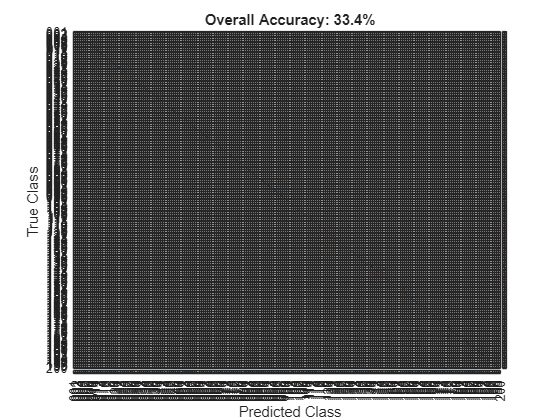


% Show confusion matrix in figure
[m, order] = confusionmat(YTest, YPred);
figure(2);
cm = confusionchart(m, order, ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized');
title("Overall Accuracy: "+ string(round(accuracy*100, 1)) +"%");

## Compute classwise positive recogniton rate

classwisePosRecog = zeros(height(order), 1);
samplesPerRow = sum(m, 2);
for iI = 1:height(order)
    classwisePosRecog(iI) = round(100 * m(iI, iI) / samplesPerRow(iI), 1);
end
disp('Classwise Recognition Rates:');

Classwise Recognition Rates:


disp(classwisePosRecog)

         0
         0
   54.5000
   33.3000
   55.6000
   37.5000
   25.0000
   55.6000
    8.3000
  100.0000
    8.3000
   90.9000
   75.0000
   66.7000
   27.3000
    9.1000
   18.2000
   55.6000
   33.3000
   50.0000
   41.7000
   90.9000
         0
   30.0000
   33.3000
   16.7000
         0
   25.0000
   16.7000
         0
    8.3000
   40.0000
   16.7000
   41.7000
   50.0000
   41.7000
   33.3000
   41.7000
         0
   33.3000
   16.7000
   50.0000
         0
   25.0000
    8.3000
   50.0000
   66.7000
   75.0000
         0
   33.3000
   16.7000
   66.7000
   58.3000
   16.7000
   50.0000
    8.3000
   41.7000
   36.4000
         0
   33.3000
   41.7000
    8.3000
   75.0000
    8.3000
   20.0000
   33.3000
    8.3000
    8.3000
   33.3000
   41.7000
         0
   16.7000
   16.7000
   75.0000
   81.8000
   16.7000
   41.7000
   33.3000
   41.7000
   25.0000
   33.3000
   33.3000
   75.0000
   33.3000
   41.7000
   25.0000
   25.0000
   41.7000
   91.7000
   41.7000
   25.0000

## Helper function for resizing images in transform

function data_out = preprocessData(data, targetSize)
try
    data_out{1} = imresize(data{1}, targetSize(1:2)); % Resize images
    data_out{2} = data{2};  % Keep labels as they are
catch e
    % This is solely for debugging
    disp(e)
end
end

## Helper function mapping image names to bounding boxes and vice versa

function image_box_map = returnMapping(ImageNames, boundingBoxes)
image_box_map = containers.Map;
for i = 1:size(ImageNames, 1)
    fn = ImageNames{i,2}{1};
    fn = split(fn, "\");
    fn = split(fn, "/");
    image_box_map(fn{end}) = [boundingBoxes{ImageNames{i,1}, 2:5}];
end
end


